clear all
blue = [0 0.4470 0.7410];
red = [0.6350 0.0780 0.1840];
purple = [.63,.13,.94];
att = red;
rep = blue;
green = [0.4660 0.6740 0.1880];
syms x y z real
syms alpha beta gamma real
syms d1 d2 d3 real

d = [d1, d2, d3];
vf = [x*(alpha-alpha*x-(alpha+beta+d1)*y+d2*z);
    y*(beta+d1*x-beta*y-(beta+gamma+d3)*z);
    z*(gamma-(gamma+alpha+d2)*x+d3*y-gamma*z)] %system (1.4)

$$vf = \left(\begin{array}{c} x\,\left(\alpha -\alpha \,x+d_{2}\,z-y\,\left(\alpha +\beta +d_{1}\right)\right)\\ y\,\left(\beta -\beta \,y+d_{1}\,x-z\,\left(\beta +d_{3}+\gamma \right)\right)\\ z\,\left(\gamma +d_{3}\,y-\gamma \,z-x\,\left(\alpha +d_{2}+\gamma \right)\right) \end{array}\right)$$

F = [x;y;z;x+y+z-1]

$$F = \left(\begin{array}{c} x\\ y\\ z\\ x+y+z-1 \end{array}\right)$$

K = F;
for i = 1:size(F,1)
    K(i) = collect(simplify(gradient(F(i),[x,y,z]).'*vf/F(i)),[x,y,z]);
end
K

$$K = \left(\begin{array}{c} \left(-\alpha \right)\,x+\left(-\alpha -\beta -d_{1}\right)\,y+d_{2}\,z+\alpha \\ d_{1}\,x+\left(-\beta \right)\,y+\left(-\beta -d_{3}-\gamma \right)\,z+\beta \\ \left(-\alpha -d_{2}-\gamma \right)\,x+d_{3}\,y+\left(-\gamma \right)\,z+\gamma \\ \left(-\alpha \right)\,x+\left(-\beta \right)\,y+\left(-\gamma \right)\,z \end{array}\right)$$



sp = solve(vf); sp = [sp.x,sp.y,sp.z]

$$sp = \begin{array}{l} \left(\begin{array}{ccc} 0 & 0 & 0\\ 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1\\ -\frac{\beta }{\alpha +d_{1}} & \frac{\alpha }{\alpha +d_{1}} & 0\\ 0 & -\frac{\gamma }{\beta +d_{3}} & \frac{\beta }{\beta +d_{3}}\\ \frac{\gamma }{d_{2}+\gamma } & 0 & -\frac{\alpha }{d_{2}+\gamma }\\ \frac{d_{3}+\gamma }{\sigma_{1}} & \frac{\alpha +d_{2}}{\sigma_{1}} & \frac{\beta +d_{1}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\alpha +\beta +d_{1}+d_{2}+d_{3}+\gamma \end{array}$$

num = [1,1,1,0,0,0] %parameters

num =      1     1     1     0     0     0



vfi = subs(vf,[alpha,beta,gamma,d],num)

$$vfi = \left(\begin{array}{c} -x\,\left(x+2\,y-1\right)\\ -y\,\left(y+2\,z-1\right)\\ -z\,\left(2\,x+z-1\right) \end{array}\right)$$


spi = solve(vfi);  spi = [spi.x,spi.y,spi.z] %equilibra

$$spi = \left(\begin{array}{ccc} 0 & 0 & 0\\ 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1\\ -1 & 1 & 0\\ 1 & 0 & -1\\ 0 & -1 & 1\\ \frac{1}{3} & \frac{1}{3} & \frac{1}{3} \end{array}\right)$$


J = jacobian(vfi,[x,y,z]) %Jacobian matrix

$$J = \left(\begin{array}{ccc} 1-2\,y-2\,x & -2\,x & 0\\ 0 & 1-2\,z-2\,y & -2\,y\\ -2\,z & 0 & 1-2\,z-2\,x \end{array}\right)$$

temp = [];
for i = 1:size(spi,1)
    if min(spi(i,:)) >= 0
        temp = [temp;i];
    end
end
spi = spi(temp,:)

$$spi = \left(\begin{array}{ccc} 0 & 0 & 0\\ 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1\\ \frac{1}{3} & \frac{1}{3} & \frac{1}{3} \end{array}\right)$$

lam = [];
ji = jacobian(vfi,[x,y,z]);
attP = []; repP = [];
for i = 1:size(spi,1)
    disp('------------------------------------------')
    spi(i,:),jii = subs(ji,[x,y,z],spi(i,:));
    lam = double(expand(eig(jii)))
    if lam < 0
        attP = [attP,i];
    elseif lam > 0
        repP = [repP, i];
    end
end

------------------------------------------


$$ans = \left(\begin{array}{ccc} 0 & 0 & 0 \end{array}\right)$$

lam =      1
     1
     1


------------------------------------------


$$ans = \left(\begin{array}{ccc} 1 & 0 & 0 \end{array}\right)$$

lam =     -1
    -1
     1


------------------------------------------


$$ans = \left(\begin{array}{ccc} 0 & 1 & 0 \end{array}\right)$$

lam =     -1
    -1
     1


------------------------------------------


$$ans = \left(\begin{array}{ccc} 0 & 0 & 1 \end{array}\right)$$

lam =     -1
    -1
     1


------------------------------------------


$$ans = \left(\begin{array}{ccc} \frac{1}{3} & \frac{1}{3} & \frac{1}{3} \end{array}\right)$$

lam =   -1.0000 + 0.0000i
   0.0000 - 0.5774i
   0.0000 + 0.5774i



vfi

$$vfi = \left(\begin{array}{c} -x\,\left(x+2\,y-1\right)\\ -y\,\left(y+2\,z-1\right)\\ -z\,\left(2\,x+z-1\right) \end{array}\right)$$

spi = double(spi)

spi =          0         0         0
    1.0000         0         0
         0    1.0000         0
         0         0    1.0000
    0.3333    0.3333    0.3333


p = spi(end,:);  %equilibrium on the invariant 2-simplex

warning('off');
axisrange = [0,1.5,0,1.5,0,1.3];
figure; hold on;

space = linspace(0,1,100);
plot3(zeros(1,100),space*axisrange(4),zeros(1,100),'k--','linewidth',1.2);
plot3(zeros(1,100),zeros(1,100),space*axisrange(6),'k--','linewidth',1.2);
plot3(space*axisrange(2),zeros(1,100),zeros(1,100),'k--','linewidth',1.2);
text('Interpreter','latex','String','$O$','Position',[0,-0.2,-0.2], 'FontSize',20);
text('Interpreter','latex','String','$x_1$','Position',[axisrange(2)+.2,-.2,0.05],'FontSize',15);
text('Interpreter','latex','String','$x_2$','Position',[-.2,axisrange(4)-.01,0.14],'FontSize',15);
text('Interpreter','latex','String','$x_3$','Position',[0,-0.3,axisrange(6)],'FontSize',15);

%plot invariant 2-simplex
fill3([1,0,0],[0,1,0],[0,0,1],'--','FaceColor',[0.93,0.91,0.91],...
    'FaceAlpha',.6,'EdgeLighting',"none")%,'EdgeColor','none')

xi = linspace(0,1,100);
plot3(xi,1-xi,zeros(1,100),'k','LineWidth',1.2)
plot3(zeros(1,100),xi,1-xi,'k','LineWidth',1.2)
plot3(xi,zeros(1,100),1-xi,'k','LineWidth',1.2)


%plot equilibria
plot3(p(1),p(2),p(3),'o','markerSize',5,'MarkerFaceColor','k','MarkerEdgeColor','k')
plot3(1,0,0,'o','markerSize',5,'MarkerFaceColor','k','MarkerEdgeColor','k')
plot3(0,1,0,'o','markerSize',5,'MarkerFaceColor','k','MarkerEdgeColor','k')
plot3(0,0,1,'o','markerSize',5,'MarkerFaceColor','k','MarkerEdgeColor','k')
plot3(0,0,0,'o','markerSize',5,'MarkerFaceColor','k','MarkerEdgeColor','k')


% plot phase trajectories
p0 = [0.5,0.1,0.2];
p0(2) = 1-p0(1)-p0(3);
[~,Y] = ode45(@df,[0,20],p0);

num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num =      1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


plot3(Y(:,1),Y(:,2),Y(:,3),'color',red,'linewidth',1.2)

p0 = [4/3,4/3,5/3];
[~,Y] = ode45(@df,[0,30],p0);

num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


plot3(Y(:,1),Y(:,2),Y(:,3),'color',red,'linewidth',1.2)

p0 = [4/3,3/4,1];
[~,Y] = ode45(@df,[0,30],p0);

num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


plot3(Y(:,1),Y(:,2),Y(:,3),'color',red,'linewidth',1.2)

p0 = [0.1,0.1,0.11];
[~,Y] = ode45(@df,[0,30],p0);

num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


plot3(Y(:,1),Y(:,2),Y(:,3),'color',blue,'linewidth',1.2)
[~,Y] = ode45(@df_pos,[0,40],p0);

num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


plot3(Y(:,1),Y(:,2),Y(:,3),'color',blue,'linewidth',1.2)

p0 = [0.05,0.2,0.05];
[~,Y] = ode45(@df,[0,30],p0);

num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


num = 1×6
     1     1     1     0     0     0


plot3(Y(:,1),Y(:,2),Y(:,3),'color',blue,'linewidth',1.2)
[~,Y] = ode45(@df_pos,[0,40],p0);

num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


num = 1×6
    -1    -1    -1     0     0     0


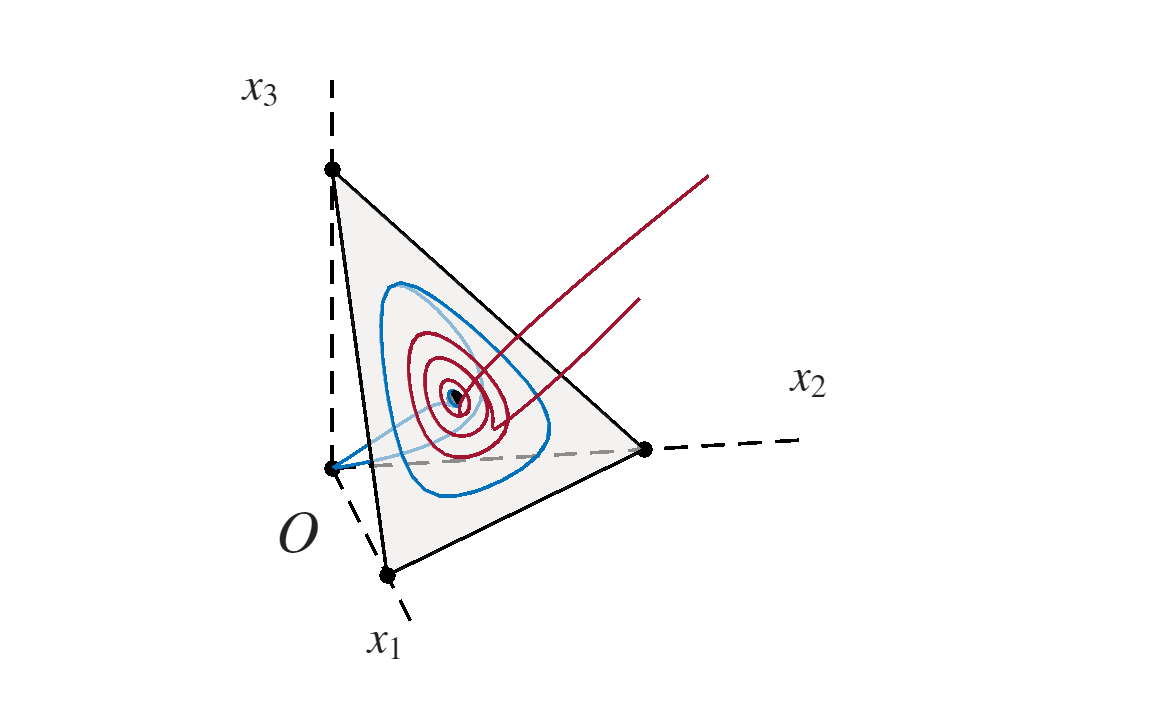

plot3(Y(:,1),Y(:,2),Y(:,3),'color',blue,'linewidth',1.2)

view(80,20)
axis equal; axis off;
axis(axisrange);
hold off
print('-dpng','-r300','fig2.1.png');

function vf = df(~,xyz)
x = xyz(1); y = xyz(2); z = xyz(3);
num = [1,1,1,0,0,0]
alpha = num(1); beta = num(2); gamma = num(3);
d1 = num(4); d2 = num(5); d3 = num(6);
vf = [x*(alpha-alpha*x-(alpha+beta+d1)*y+d2*z);
    y*(beta+d1*x-beta*y-(beta+gamma+d3)*z);
    z*(gamma-(gamma+alpha+d2)*x+d3*y-gamma*z)];
end


function vf = df_pos(~,xyz)
x = xyz(1); y = xyz(2); z = xyz(3);
num = - [1,1,1,0,0,0]
alpha = num(1); beta = num(2); gamma = num(3);
d1 = num(4); d2 = num(5); d3 = num(6);
vf = [x*(alpha-alpha*x-(alpha+beta+d1)*y+d2*z);
    y*(beta+d1*x-beta*y-(beta+gamma+d3)*z);
    z*(gamma-(gamma+alpha+d2)*x+d3*y-gamma*z)];
end